# Fuel Economy Analysis

This is an example of data analysis on historical fuel economy data. We have data from various cars built from year 2000 up to 2012. In this report, we will automate importing data from spreadsheets, creating customized plots, splitting data into groups, and interactively applying custom curve fits.

We can share our results using an interactive Fuel Economy App or by exporting this Live Script as documentation of our analysis.

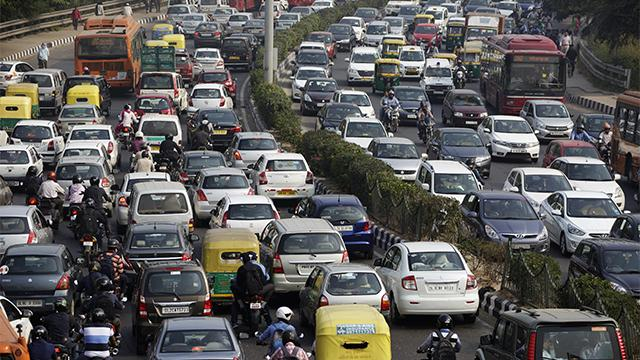

## Import Data into Table

Import the data from Excel using a modified auto-generated function from the Import Tool. 

data = importData(2007)

data = 2595×24 table
    Year        MfrName              CarLine           Car_Truck    EngDisp    Police    RatedHP    Transmission    Drive    Weight    Comp    AxleRatio    EVSpeedRatio    AC    PRP    FuelType    City_Highway     HC       CO     CO2    NOX     MPG     Valves_Cyl    CoastDownTime
    ____    _______________    ____________________    _________    _______    ______    _______    ____________    _____    ____

Look at a quick summary of some of the variables of interest.

summary(data(:,{'RatedHP','MPG','Car_Truck'}))

Variables:
    RatedHP: 2595×1 double
        Values:
            Min          76   
            Median      236   
            Max         631   
    MPG: 2595×1 double
        Values:
            Min          9.8  
            Median      24.8  
            Max         66.6  
    Car_Truck: 2595×1 categorical
        Values:
            car        1343  
            truck      1252  


## Visualize Data

Plot MPG versus Rated Horsepower.

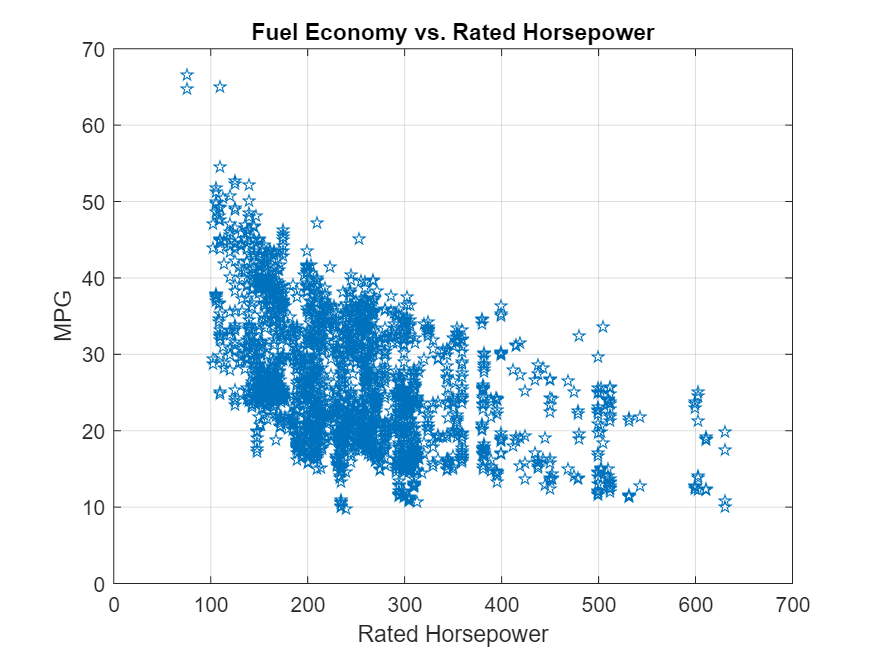

createMPGFigure(data.RatedHP, data.MPG);

## Visualized Data in Groups

We can easily visualized grouped data using a grouped scatter plot. Notice there are clear "bands" of data; we may find it useful to separate these bands into distinct datasets and analyze them independently.

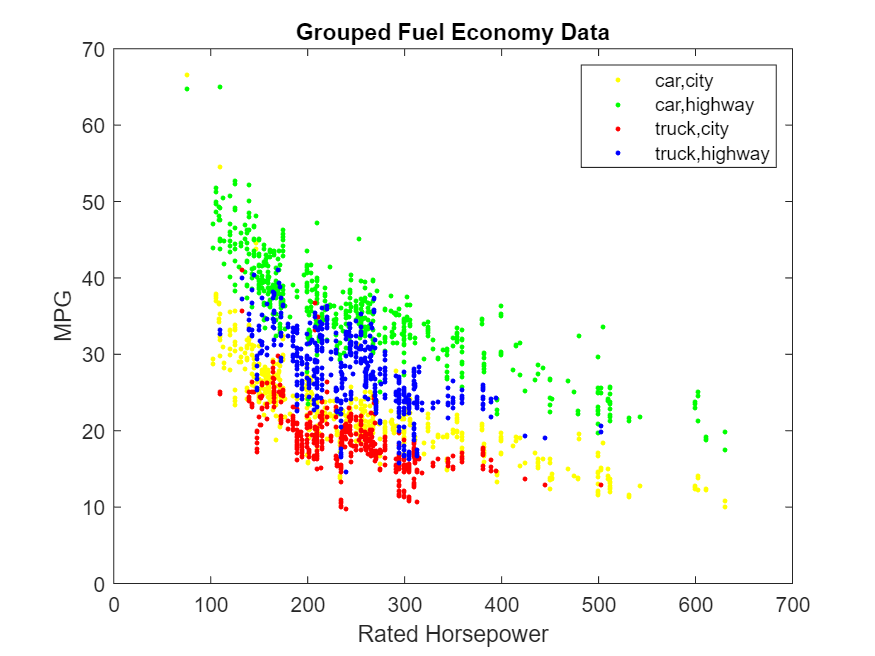

figure
gscatter(data.RatedHP, data.MPG, ...
    {data.Car_Truck, data.City_Highway}, ...
    'ygrb', '.', 7, 'on', 'Rated Horsepower', 'MPG')
title('Grouped Fuel Economy Data')

## Examine Grouping Effects of Categorical Data

The spread of the data in the plot above leads us to believe there may be other factors affecting the fuel economy of vehicles. To explore this, we will separate the data using [logical array indexing](matlab: web(fullfile(docroot, 'matlab/matlab_prog/find-array-elements-that-meet-a-condition.html'))). 

For example, we can extract data for cars only:

carIDs = data.Car_Truck == "car";
carData = data(carIDs,:);

Similarly, we can create logical indices in order to extract data for cars or trucks in the city:

city_carIDs = (data.City_Highway == "city" & data.Car_Truck == "car");

Or city/highway only:

cityIDs = data.City_Highway == "city";
highwayIDs = data.City_Highway == "highway";
RatedHPcarCity = data.RatedHP(city_carIDs);
MPGcarCity     = data.MPG(city_carIDs);

## Fit a Custom Equation

We can consider fitting a standard curve (polynomial, power, etc.) to our dataset, but in this case, we already know the general form of the variable relationships. 


$$\textrm{MPG}=b_1 +\frac{b_2 }{\textrm{RatedHP}}$$


We can use this equation to fit a custom curve to our data using the [Curve Fitting Tool](matlab: cftool). 

Let's first examine only data in the city.  We can extract this data for curve fitting by using the logical index we generated in the previous section.

RatedHPCity = data.RatedHP(cityIDs);
MPGCity     = data.MPG(cityIDs);

The following is a modified version of the auto-generated code from the Curve Fitting Tool.

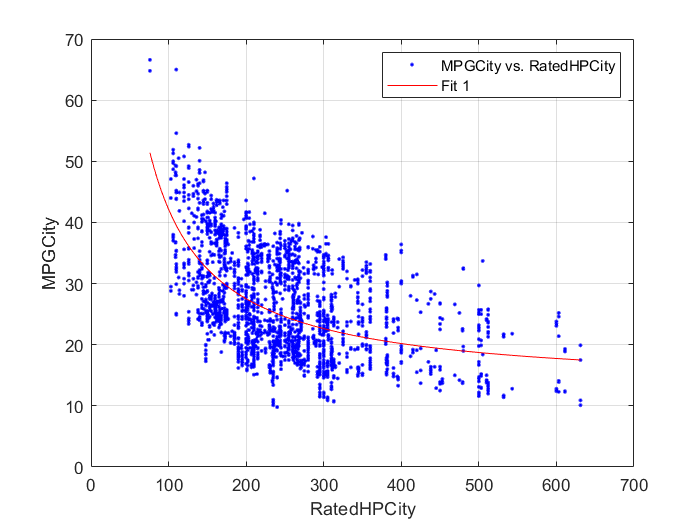

cf = createMPGFit(data.RatedHP, data.MPG);

## Plot Data and Model

The result from the Curve Fitting Toolbox has a `plot` method for displaying the result graphically. We can choose to display the 95% prediction bounds for the fit.

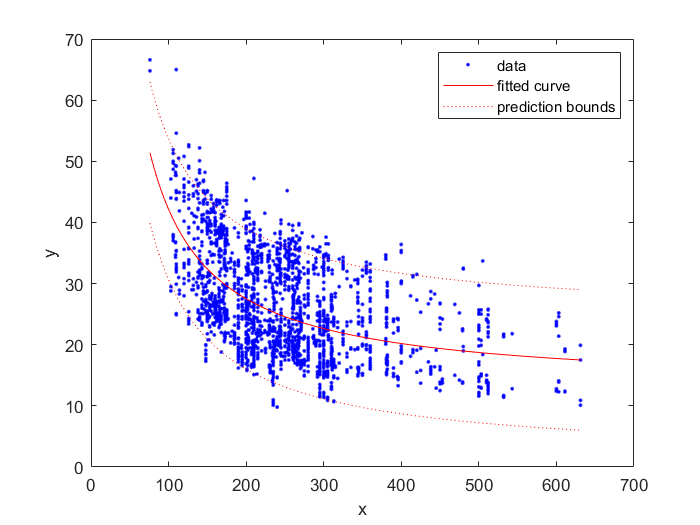

figure
plot(cf, 'r', data.RatedHP, data.MPG, 'PredObs', 0.90);

## Plot Grouped Data and Model

We will apply the similar modeling technique to the data for different combinations of groups (Car-Truck and City-Highway)

Model different combinations:

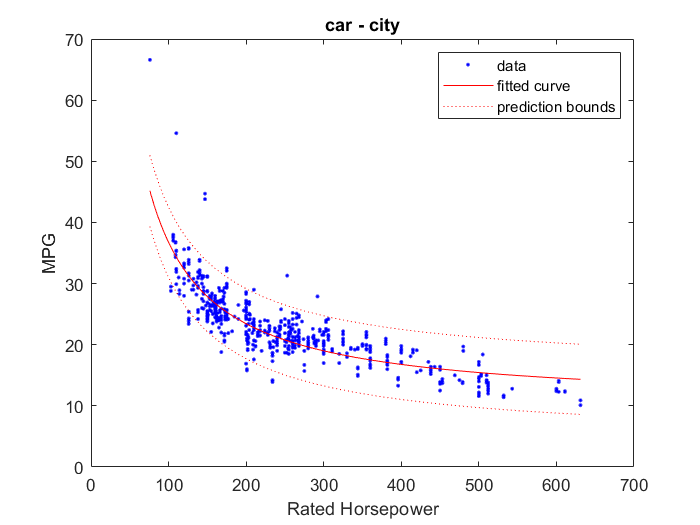

mdlCC =      Linear model:
     mdlCC(x) = a + b*1/x
     Coefficients (with 95% confidence bounds):
       a =       10.12  (9.528, 10.72)
       b =        2663  (2546, 2779)

gofCC = struct with fields:
           sse: 5.690594401270628e+03
       rsquare: 0.749623904309536
           dfe: 670
    adjrsquare: 0.749250208644327
          rmse: 2.914348036784282

[mdlCC, gofCC] = modelMPG(data, 'car', 'city')

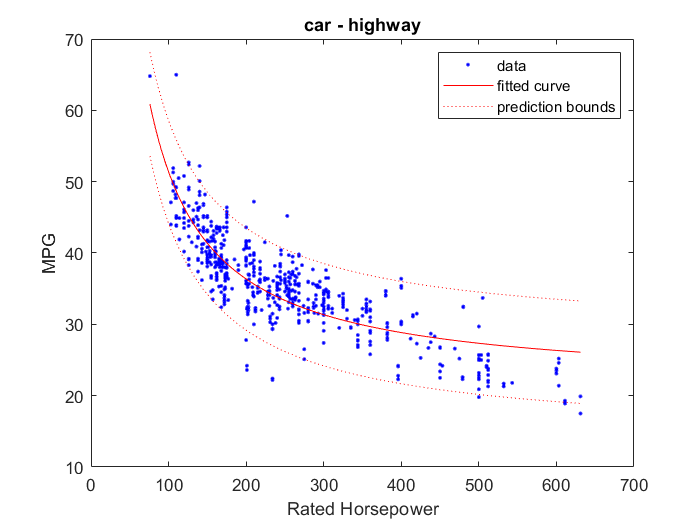

mdlCH =      Linear model:
     mdlCH(x) = a + b*1/x
     Coefficients (with 95% confidence bounds):
       a =       21.33  (20.58, 22.09)
       b =        3005  (2857, 3153)

gofCH = struct with fields:
           sse: 8.894802123873078e+03
       rsquare: 0.703276453078526
           dfe: 669
    adjrsquare: 0.702832920123486
          rmse: 3.646322578516132

[mdlCH, gofCH] = modelMPG(data, 'car', 'highway')

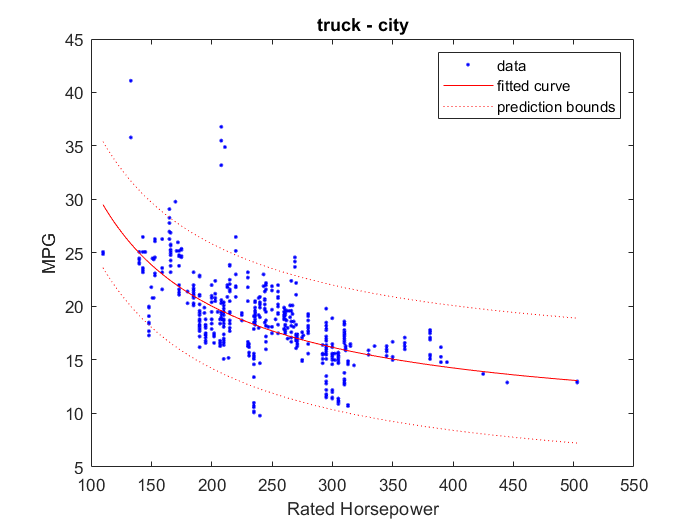

mdlTC =      Linear model:
     mdlTC(x) = a + b*1/x
     Coefficients (with 95% confidence bounds):
       a =       8.473  (7.579, 9.368)
       b =        2314  (2115, 2514)

gofTC = struct with fields:
           sse: 5.478216572711459e+03
       rsquare: 0.453974710197665
           dfe: 625
    adjrsquare: 0.453101069733981
          rmse: 2.960599013094873

[mdlTC ,gofTC] = modelMPG(data, 'truck', 'city')

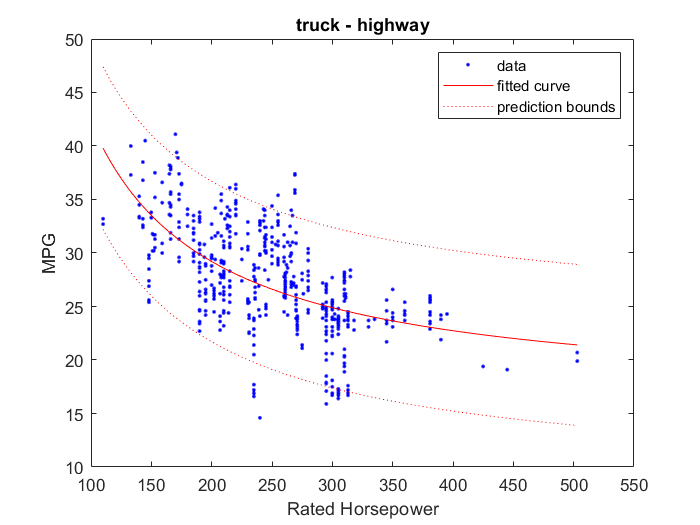

mdlTH =      Linear model:
     mdlTH(x) = a + b*1/x
     Coefficients (with 95% confidence bounds):
       a =       16.26  (15.11, 17.42)
       b =        2589  (2332, 2846)

gofTH = struct with fields:
           sse: 9.067936770149394e+03
       rsquare: 0.385689969390750
           dfe: 623
    adjrsquare: 0.384703917977252
          rmse: 3.815137705840447

[mdlTH, gofTH] = modelMPG(data, 'truck', 'highway')

*Copyright 2021 The MathWorks, Inc.*